# Signals and Systems

## Introduction

Signal processing studies *signals* and *systems*

Signal:

- A detectable physical quantity... by which messages or information can be transmitted

- Signals carry information (physical such as natural frequencies and damping ratio)

systems:

- Manipulate the information carried by signals

Goals:

- Spectral analysis of vibration measurement, system identification (modal analysis)

Prerequisites that you have a solid understanding of

- Complex numbers and arithmetic

- Linear algebra (vector, matrix, dot products, eigenvectors, basis, ...)

- Matlab or python

## Practice in matlab

Q1: You must define a sinusoid of amplitude 1 during 5 cycles and no phase shift with a sampling period of 0.01s. visualize the time signal.

%Q1
dt = .01; 
maxt = 1;
t = 0:dt:(maxt-dt);
nt = length(t);  %length of t

nCycles = 5;
amp = 1; 
phase = 0;
y5 = amp*cos(2*pi*t*nCycles-pi*phase/180); 


A **signal** x[n] is a function that maps an independent variable to a dependent variable.

In this course, we will focus on discrete-time signals x[n]:

- Independent variable is an integer: n ∈ ℤ

- Dependent variable is a real or complex number: x[n] ∈ ℝ or ℂ

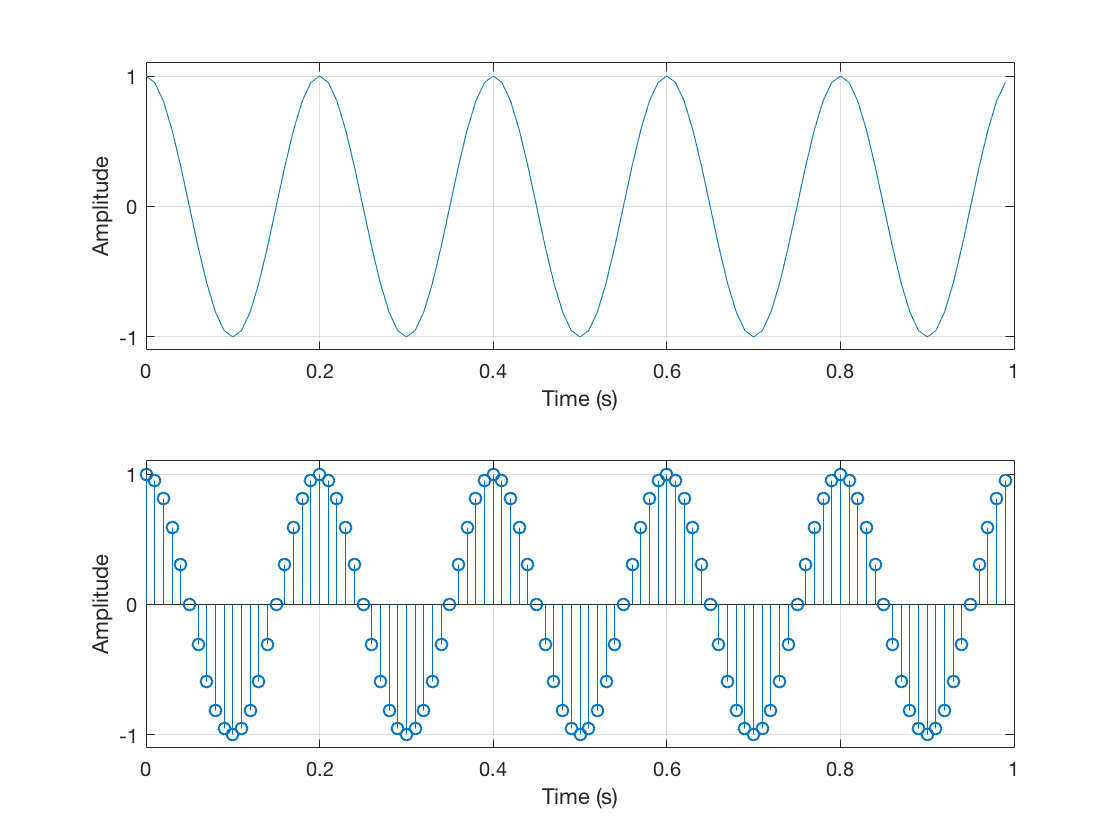

figure 
subplot(2,1,1);plot(t,y5); xlabel('Time (s)'); set(gca,'XTick',0:.2:maxt); set(gca,'YTick',-1:1); ylabel('Amplitude'); set(gca,'YLim',amp*1.1*[-1,1]);  %'grid' draws dotted lines at the x and y-tick values 
grid;
subplot(2,1,2);stem(t,y5); xlabel('Time (s)'); set(gca,'XTick',0:.2:maxt); set(gca,'YTick',-1:1); ylabel('Amplitude'); set(gca,'YLim',amp*1.1*[-1,1]);  %'grid' draws dotted lines at the x and y-tick values 
grid

Q2: The sinusoid has a frequency of 5 Hz (5cycles in 1s). You will now compute the spectrum of y5 using 'fft'


%Q2
Y5 = fft(y5); 
%size of y5 and Y5 ?
whos y5 Y5 

  Name      Size             Bytes  Class     Attributes

  Y5        1x100             1600  double    complex   
  y5        1x100              800  double              



%Class of Y ?
Y5(1:10)'

ans =    0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  50.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i


The Fourier Transform is method for representing a 1-dimensional vector (like a time-series) in terms of 'frequencies'. It is typically used to find periodic signals buried in noise, and to design filters that only pass through a specific range of frequencies.

There is an amazing theorem that states that any finitely sampled time-series can be perfectly reconstructed as a sum of a finite number of sinusoids. Moreover, if there are n time-points, then only n/2 sinusoids will be needed.

A sinusoid is defined by three variables, the frequency, the amplitude and the phase. The frequency of the sinusoids needed to reconstruct a time-series is determined by the length of the time series. The first sinusoid will have exactly one cycle, the second will have two cycles, and so on. There's one more sinusoid which has 'zero' frequency, sometimes called the 'dc' (from electrical engineering). This is the mean of the time-series and therefore determines the vertical offset.

Fourier transforms on discretely sampled data are almost always done through an algorithm called the 'Fast Fourier Transform', or FFT. This is a very efficient algorithm (originally developed by Gauss) that is available in all mathematical sofware programs, including Matlab.

Q3: Now add a new sinusoid of amplitude 2 and phase shift 30 ° to the graph. View 7 cycles.

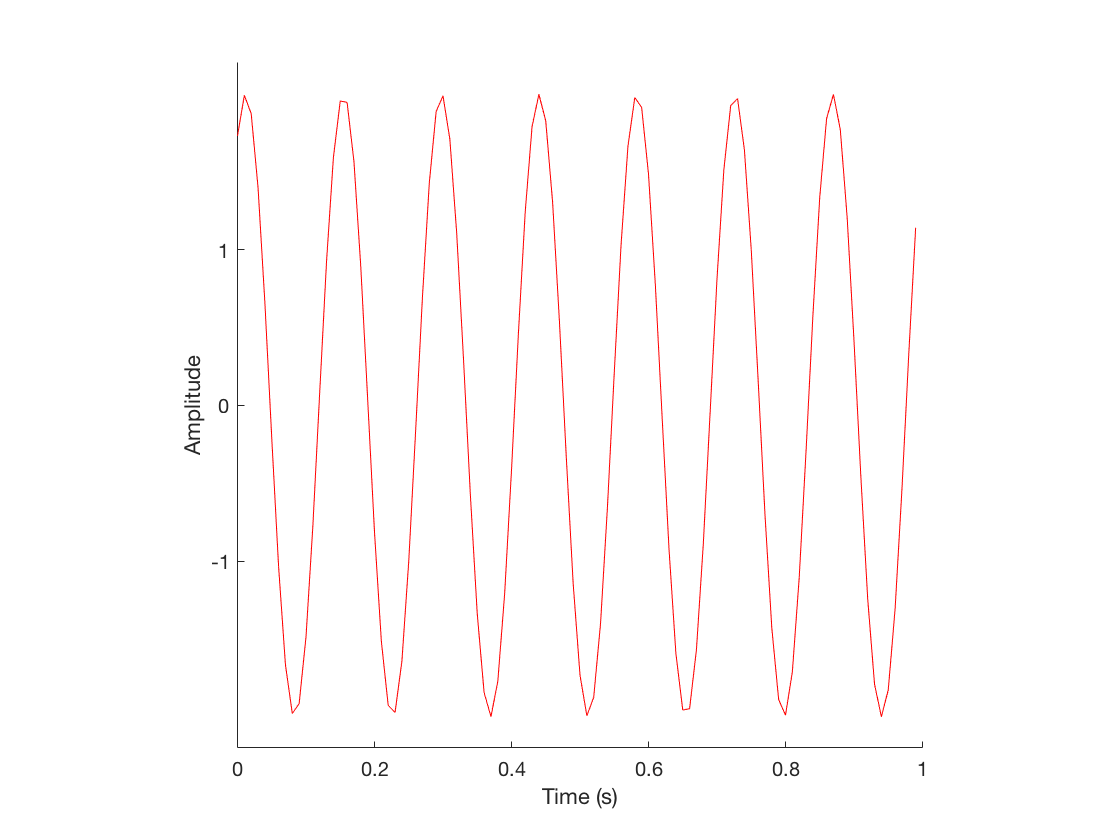

%Q3
nCycles = 7; 
amp = 2;  %around 1.15 
phase = 30;  %degrees  
y7 = amp*cos(2*pi*t*nCycles-pi*phase/180); 
figure
hold on
plot(t,y7,'r-'); xlabel('Time (s)'); 
set(gca,'XTick',0:.2:maxt); 
set(gca,'YTick',-1:1); 
ylabel('Amplitude'); 
set(gca,'YLim',amp*1.1*[-1,1]);
axis square 
grid off  

Y7 = fft(y7);


Q4: Compare the phase of Y5 and Y7 by plotting the graph part real vs part imaginary (cycle)

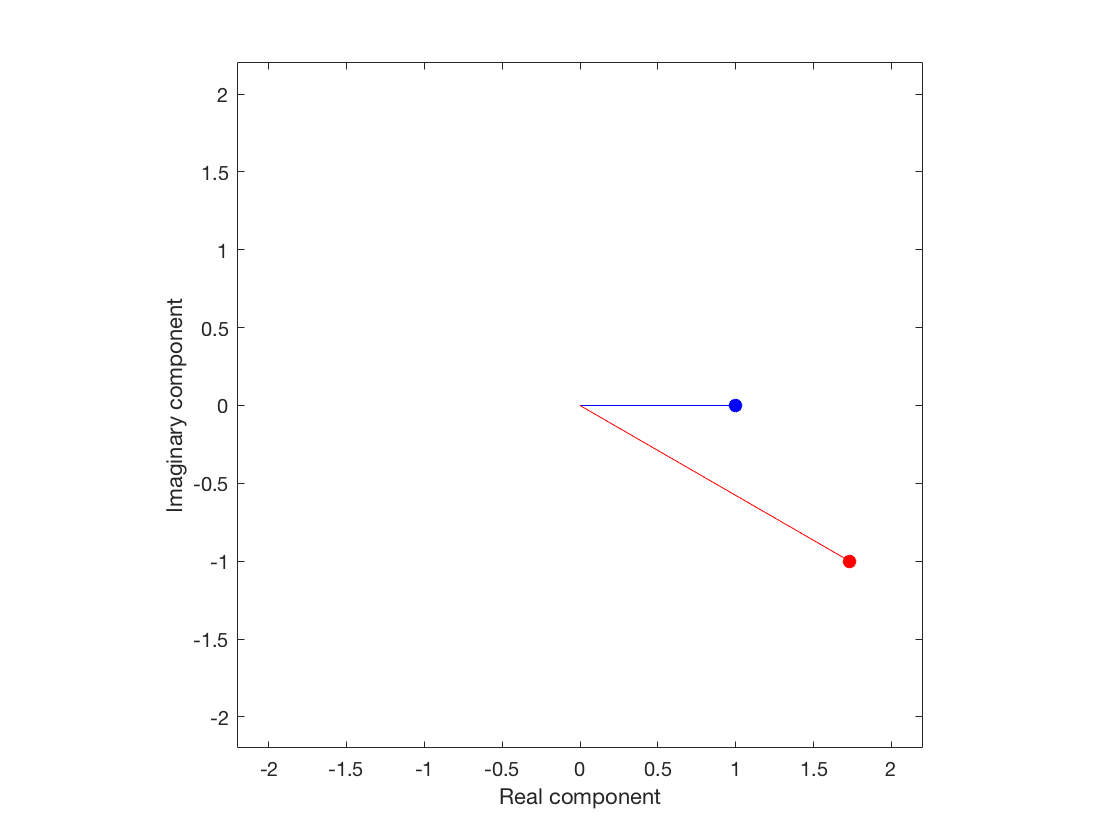


%Q4
figure
plot([0,2*Y5(6)/nt],'b-'); hold on
h5=plot(2*Y5(6)/nt,'bo','MarkerFaceColor','b');
axis equal  
xlabel('Real component')
ylabel('Imaginary component');
hold on
plot([0,2*Y7(8)/nt],'r-');
h7= plot(2*Y7(8)/nt,'ro','MarkerFaceColor','r');
set(gca,'XLim',1.1*amp*[-1,1]); 
set(gca,'YLim',1.1*amp*[-1,1]);



amp5 = 2*abs(Y5(6))/nt; 
phase5 = -180*angle(Y5(6))/pi;
amp7 = 2*abs(Y7(8))/nt; 
phase7 = -180*angle(Y7(8))/pi;


Q5: We generate a more complicated sinusoid

Y57 = y5 + y7. Compute and visualize the spectrum

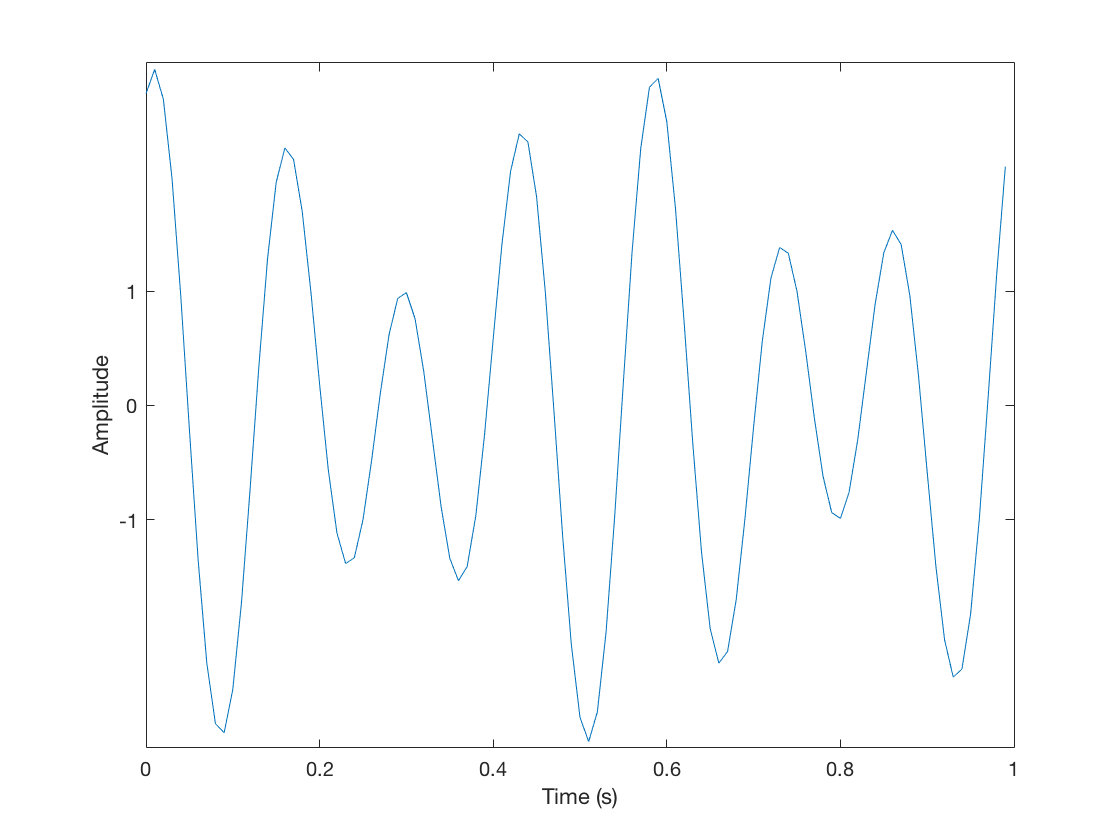


%Q5
y57 = y5+y7;  
figure 
plot(t,y57); xlabel('Time (s)');
set(gca,'XTick',0:.2:2); 
set(gca,'YTick',-1:1); ylabel('Amplitude');

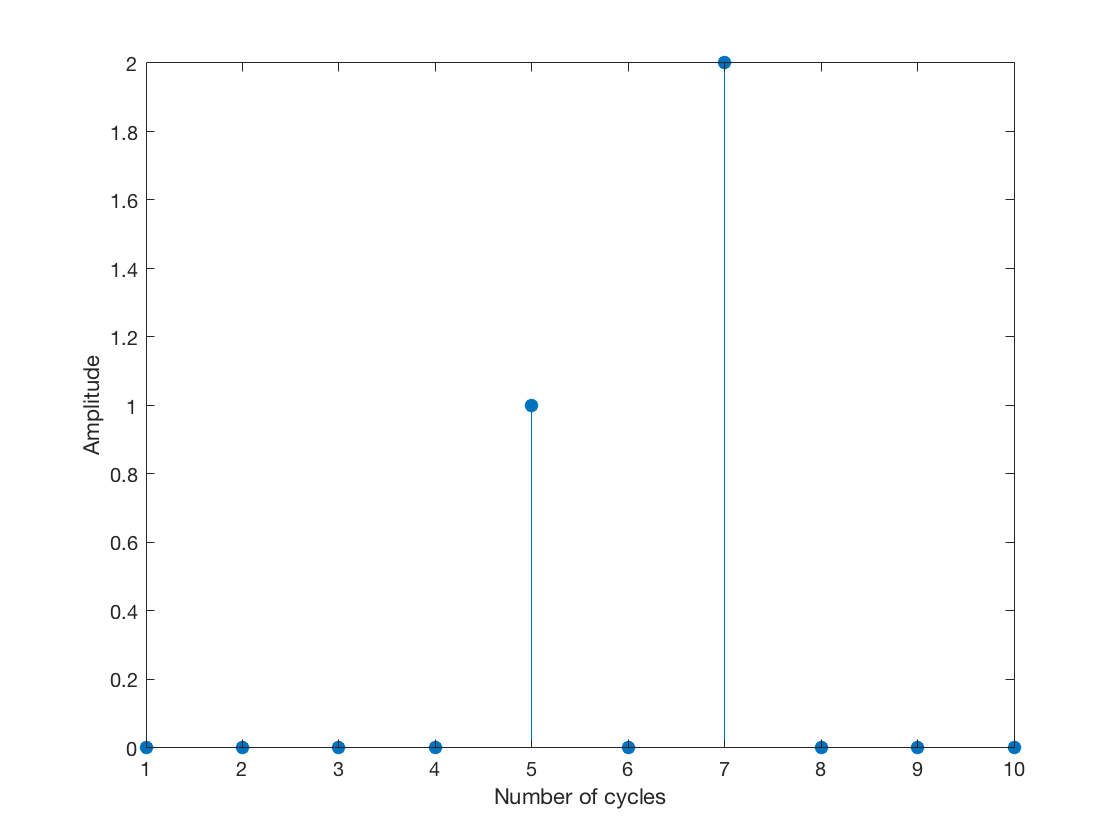



%Tracer son spectre en utilisant ?fft?

Y57 = fft(y57);  
% We'll plot the amplitudes of the first 10 sinusoids as a 'stem' plot 
id = 2:11;  %sinusoids of periods 1 through 10  
figure
stem(2*abs(Y57(id))/nt,'fill')  
xlabel('Number of cycles') 
ylabel('Amplitude');

See how there are only two non-zero amplitudes - the two sinusoids corresponding to 5 and 7 cycles, which is how we built the sinusoid. This illustrates the 'linear' property of the fft: The fft of the sum of two time-series is the same as the sum of the fft of each time series. It also shows a conventional way to represent the results of an fft. By showing only the amplitude we've lost our phase information. Because of this, people often forget to consider the phase of the fft.

Q6: "Whole" spectrum calculation

On the whole calculated spectrum, we consate a mirror symmetry with respect to Fs / 2, the amplitudes are doubled

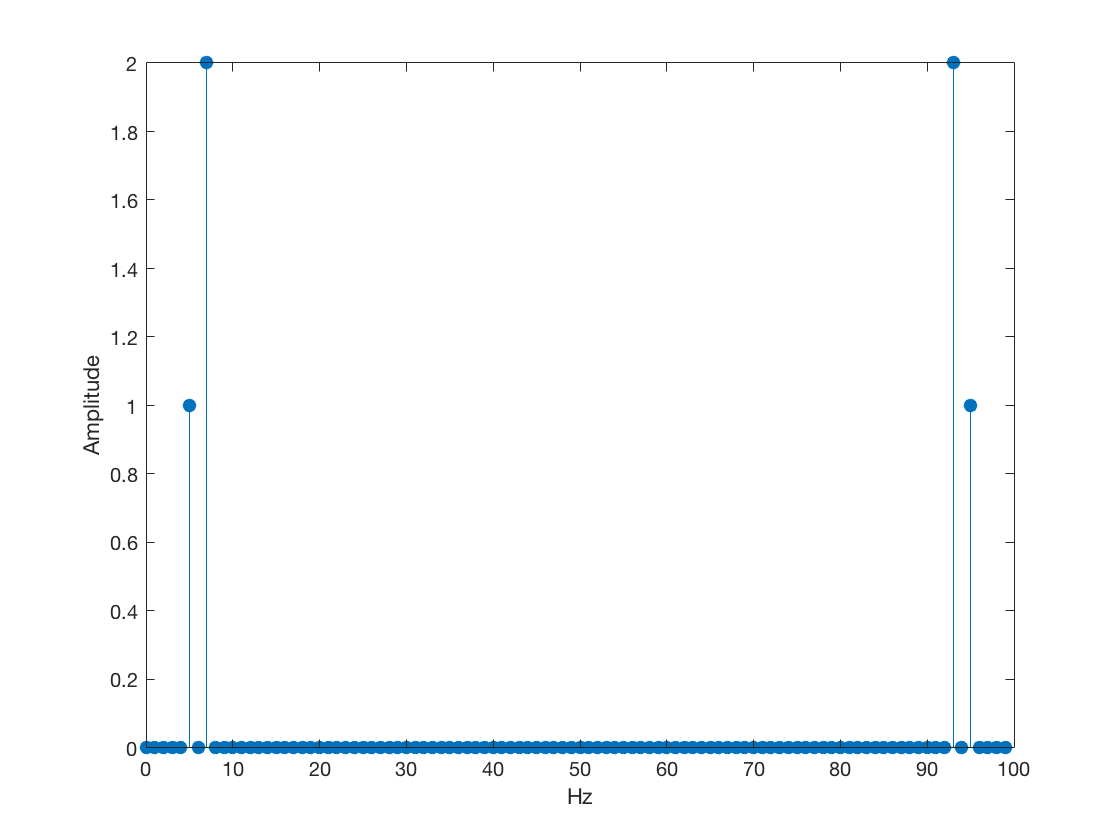

%Q6
Fs=1/dt;
F=(0:nt-1)*Fs/nt;
figure
stem(F,2*abs(Y57)/nt,'fill') 
xlabel('Hz');
ylabel('Amplitude');

The fft is a 'lossless' transformation, meaning that no information is lost. Because of this (and because the sinusoids are mutually 'orthogonal') if there are nt timepoints in our time-series, then exactly nt numbers are needed to represent the transformation. The output of the fft has nt values in it - but each of these values are complex so they 'contain' two numbers. So the output of the fft has twice as many numbers as the input. 

Q7: 2 interesting spectrum examples for time-frequency equivalence

An interesting example is the 'delta' function - zeros everywhere except for one value;

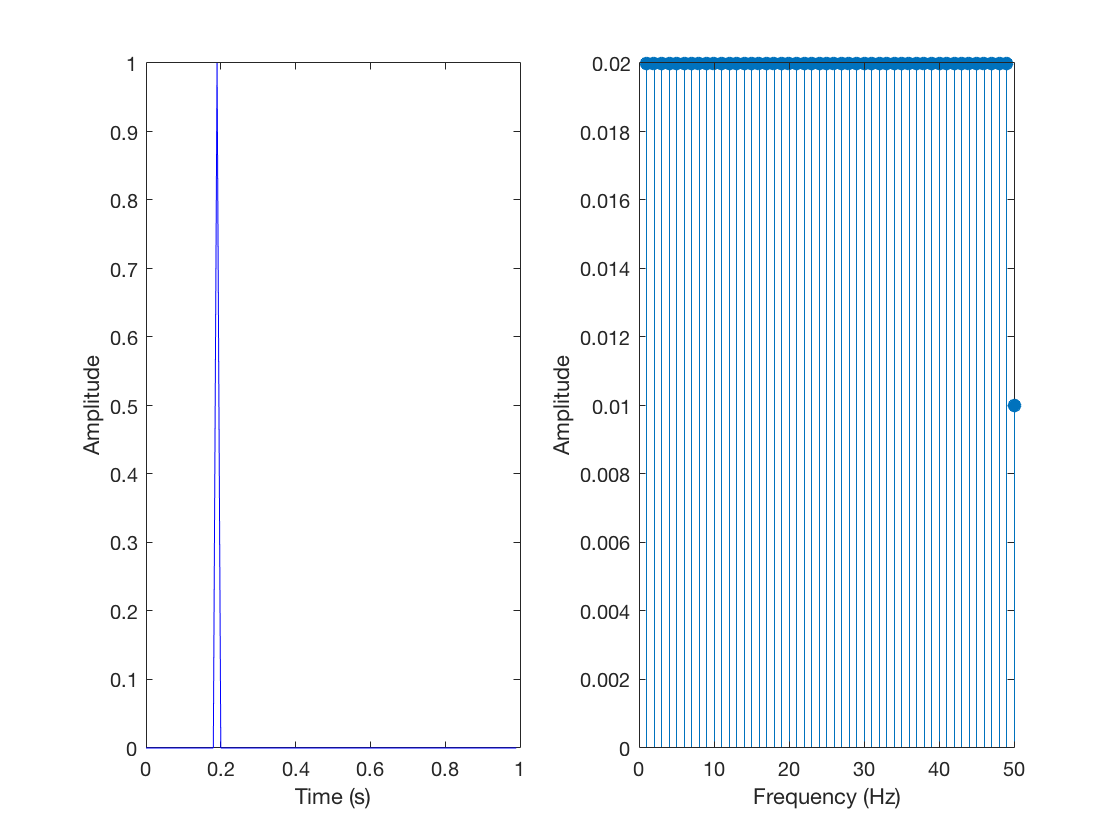

%Q7
figure;
y = zeros(size(t)); y(20) = 1;  plotfft(t,y); %can use fftshift also

Another example is 'white' noise, where every time point is an independent draw from a normal distribution:

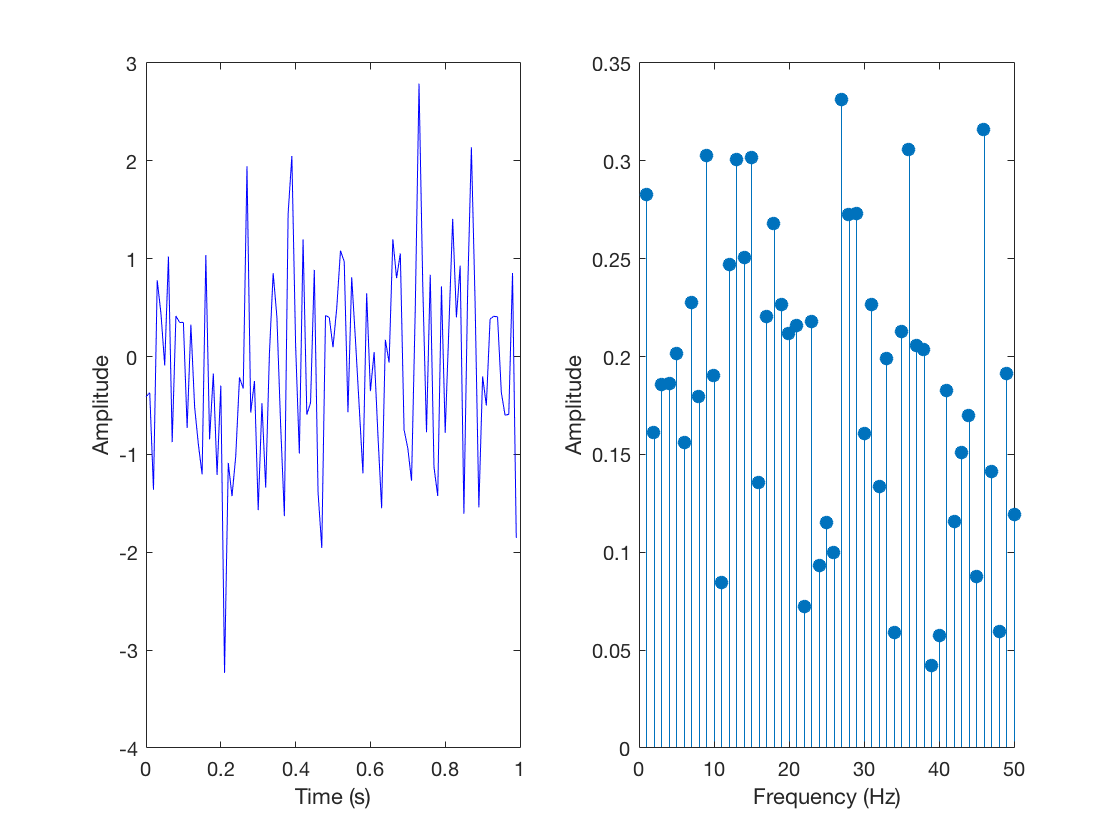

figure;
y = randn(size(t)); plotfft(t,y);

The amplitude spectrum looks like noise too. These amplitudes are also normally distributed with equal probability across all frequencies. White noise contains sinusoids of all frequencies - it's called 'white' presumably because 'white' light contains light of all wavelengths in the spectrum.Fourier transforms are good at detecting periodic signals buried in noise that is otherwise very difficult to see in the time-series. As an example, we'll add a 12-cycle sinusoid to the random time-series that we just looked at:

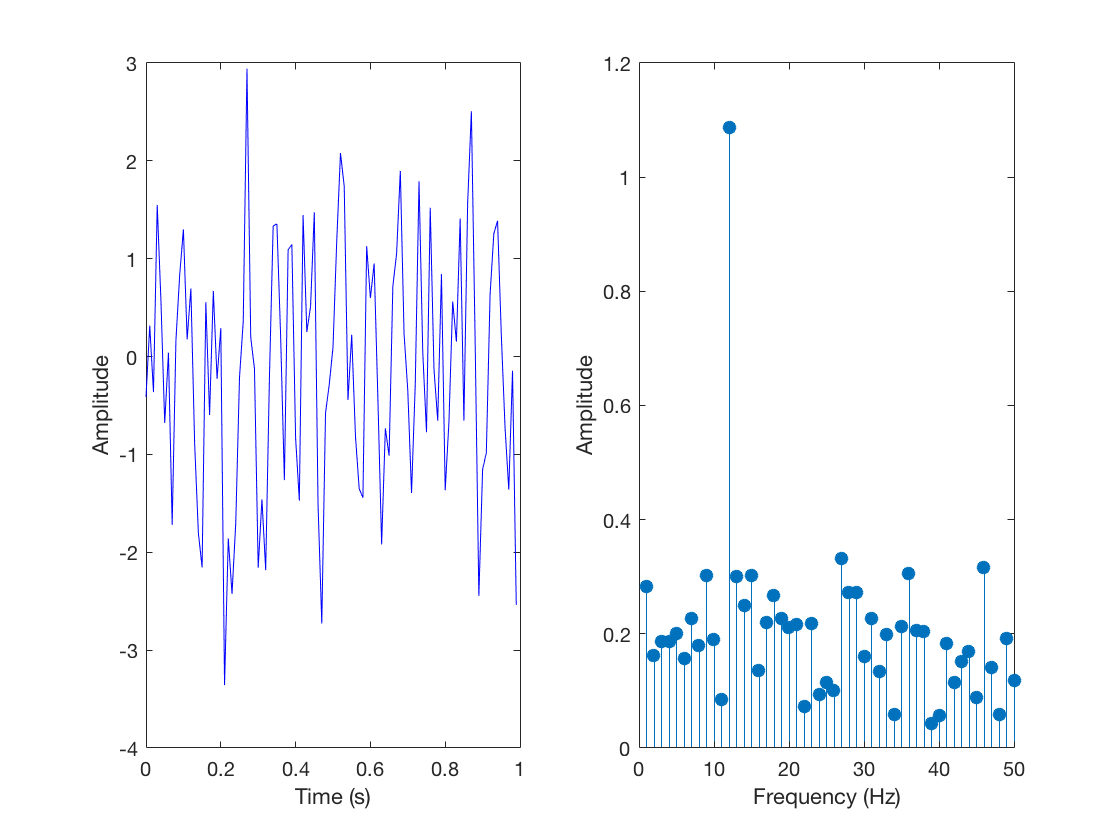

figure;
nCycles = 12; y = y+sin(2*pi*nCycles*t); plotfft(t,y);

Q8; visualisation of a song. The file contains two variables, the time-course of the sound, y and the sampling rate, Fs (in Hz). We can create our own time vector from this information:

% %Q8
 load handel 
% %The file contains two variables, the time-course of the sound, y and the sampling rate, Fs (in Hz). We can create our own time vector from this information:
% maxt = length(y)/Fs;
% t = linspace(0,maxt,length(y));  
% % Here's a plot of the time-course of the sound hander
% % 
% % figure
% % plot(t,y);
% % xlabel('Time (sec)');
% 
% %Listen
% %pause;
% %ylim = get(gca,'YLim');
% %timeH = plot([0,0],ylim','r-','LineWidth',2);  
% sound(y,Fs);  tic 
% % while toc<maxt     
% % set(timeH,'XData',toc*[1,1])     
% % drawnow 
% % end  
% % delete(timeH);
% 
% %Signal visualization
% figure;
% plotfft(t,y);

Q9: Let's zoom in...

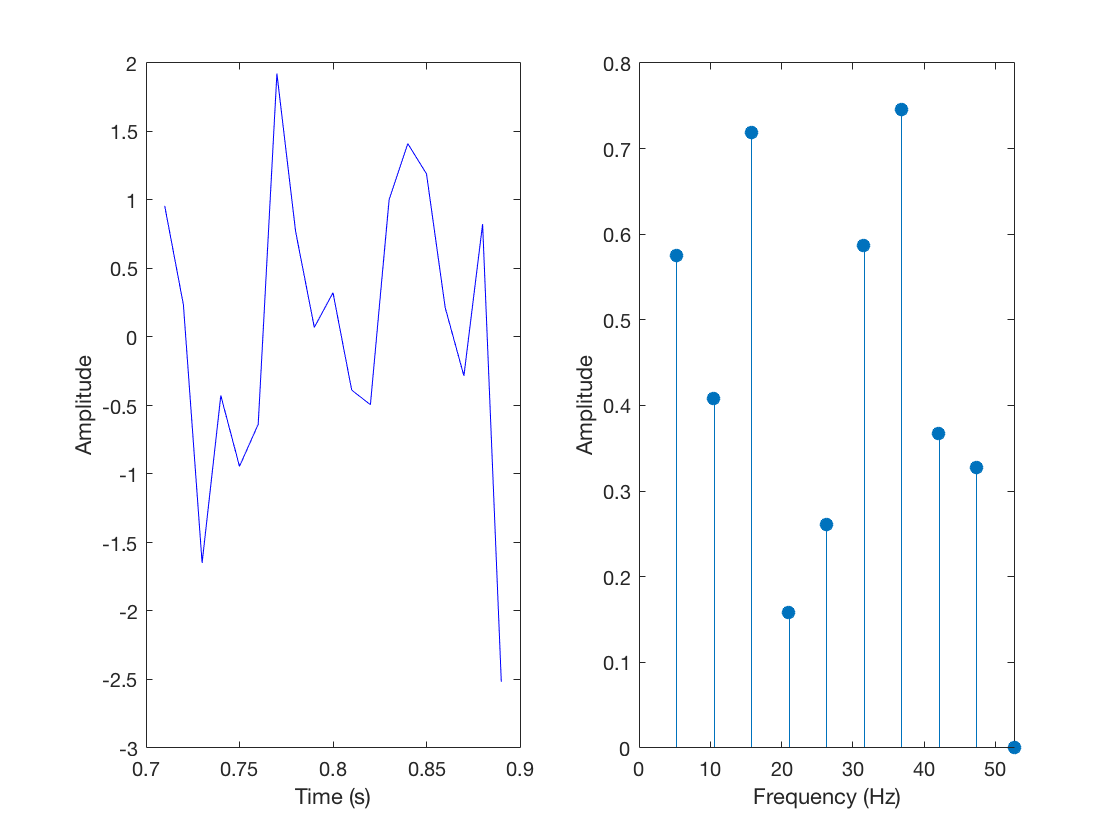

% %Q9
% tLo = .7; tHi = .9;  
% y1 = y(t>tLo & t<tHi); 
% maxt = length(y1)/Fs; 
% t1 = t(t>tLo & t<tHi);  %linspace(0,maxt,length(y1));
% figure;
% sound(y1,Fs);
plotfft(t1,y1) ;

Q10:  when you "average" short signal window with overlap and sum the local spectrum... you create a more "precise" spectrum

type help periodogram 

[http://www.mathworks.fr/fr/help/signal/ug/spectral-analysis.html](http://www.mathworks.fr/fr/help/signal/ug/spectral-analysis.html)

Let's try to see how these local spectrums?

% %Q10
% figure
% spectrogram(y,256,120,256,Fs); % Display the spectrogram
% 


Q11: How do you estimate a transfer function from a displacement signal measured so called ys and from measured force siganl u (both depend on time t)?

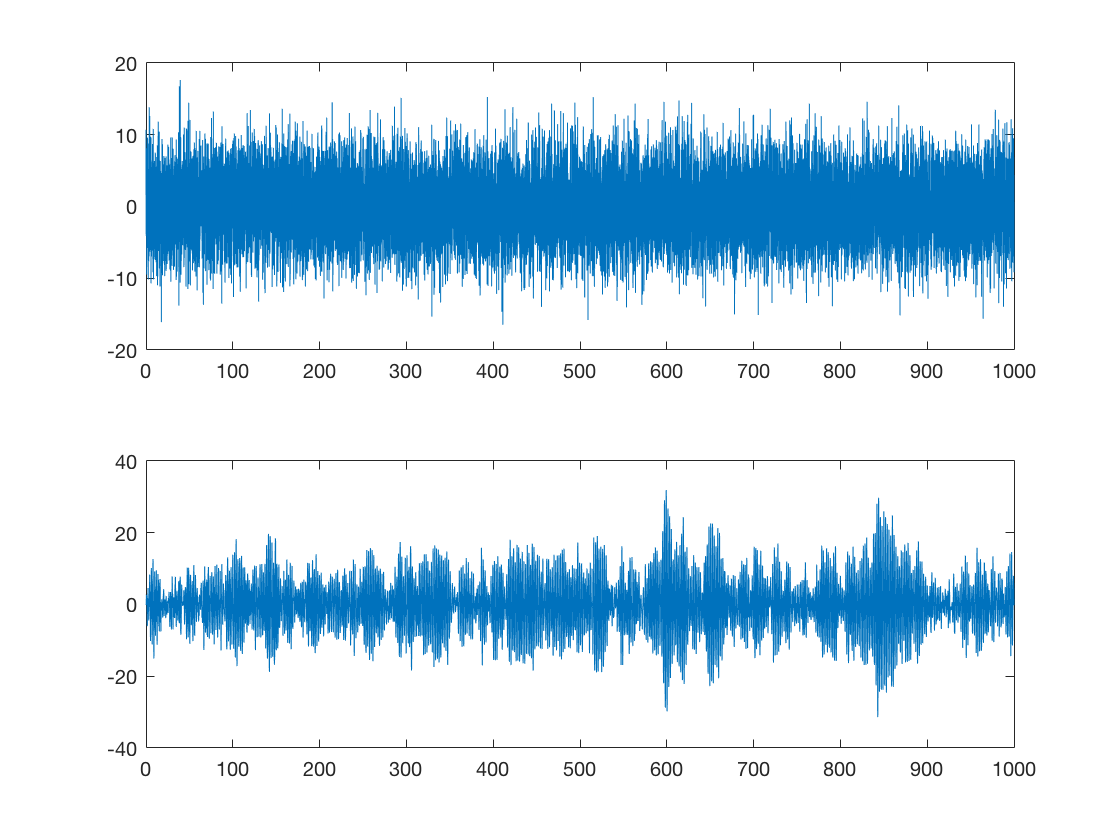

%Q11
Ts=0.05;
Fs=1/Ts;
load data;
u=data(:,1);
ys=data(:,2);
t=0:Ts:(length(u)-1)*Ts;
figure; subplot(211);plot(t,u);subplot(212);plot(t,ys);

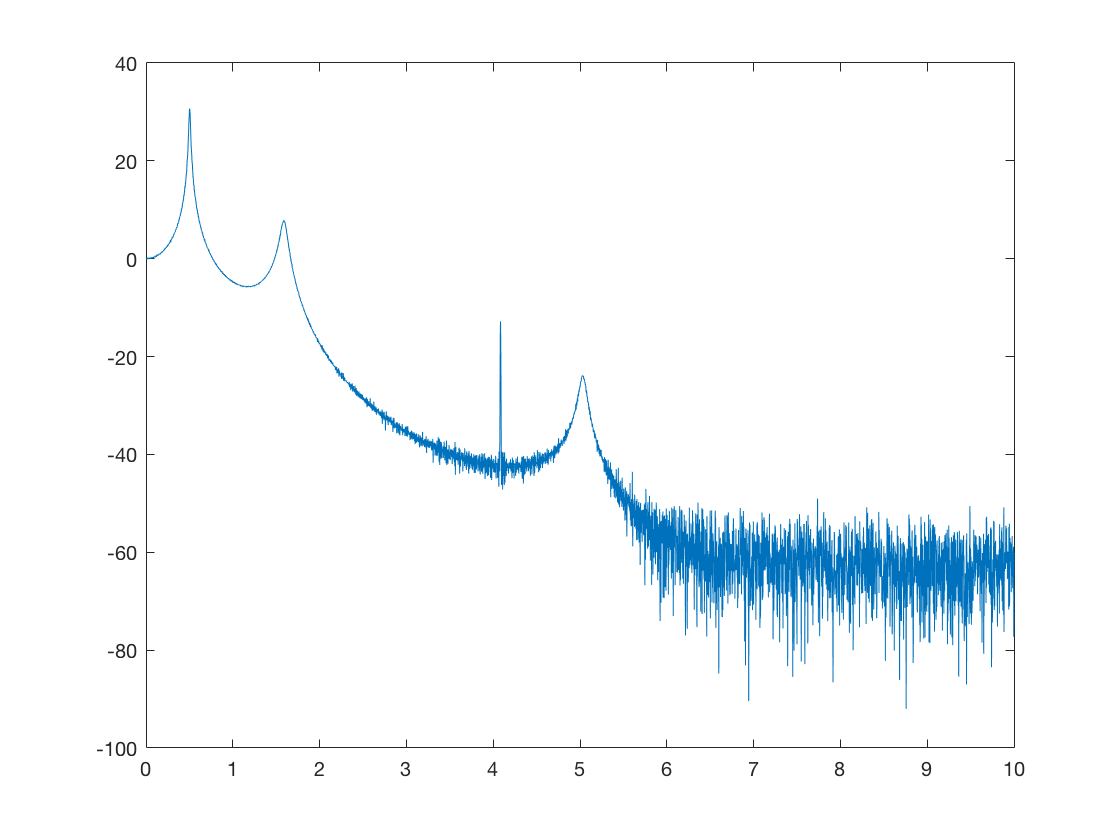

[txy,f]=tfestimate(u,ys,[],[],[],Fs);
figure
plot(f,20*log10(abs(txy)))

That's system identification!

But does it exist a model to fit to this data? May be using an analytical transfer function (Mathematical Models of LTI) ?

[https://www.youtube.com/embed/RJleGwXorUk](https://www.youtube.com/embed/RJleGwXorUk)

Let's start by computing a transfer function G where s is the Laplace variable $j \omega$


$$G(s) = \frac{s+5}{s^4+2s^3+3s^2+4s+5}$$


num = [1,5];
den = [1,2,3,4,5];

G = tf(num,den)


G =
 
              s + 5
  -----------------------------
  s^4 + 2 s^3 + 3 s^2 + 4 s + 5
 
Continuous-time transfer function.



In structural mechanics a resonator is a second order tf described as $G(s) = \frac{\omega_{n}^{2}}{s^2+2\zeta \omega_{n}s + \omega_{n}^{2}}$

Let's compute its step response for several $\zeta$

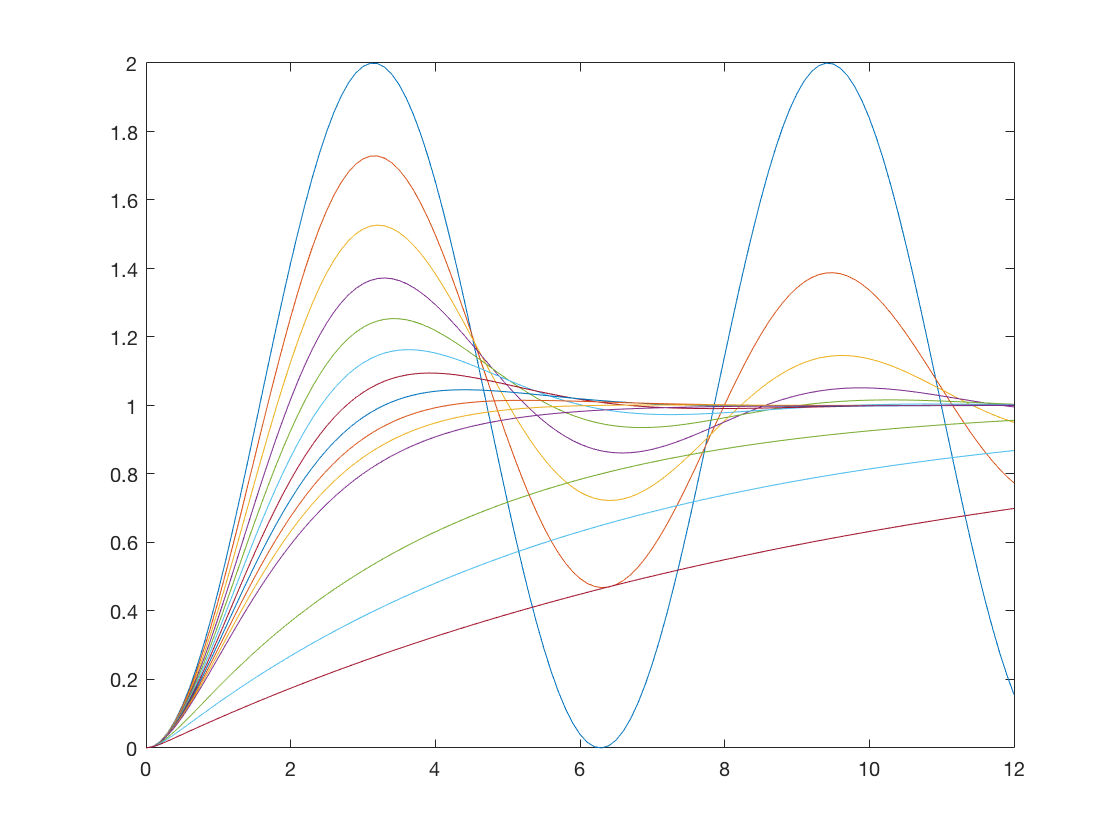

wn = 1; 
yy = []; 
t = 0:.1:12; 
zet = [0:0.1:0.9, 1+eps,2,3,5];
for i = 1:length(zet)
    G = tf(wn^2,[1 2*zet(i)*wn,wn^2]); 
    [y,tout] = step(G,t);
    yy = [yy; y'];
end

plot(tout,yy)

and in the frequency domain? Let's take a physical (damped mode) case with $\omega_n=10$ and $\zeta=0.2$

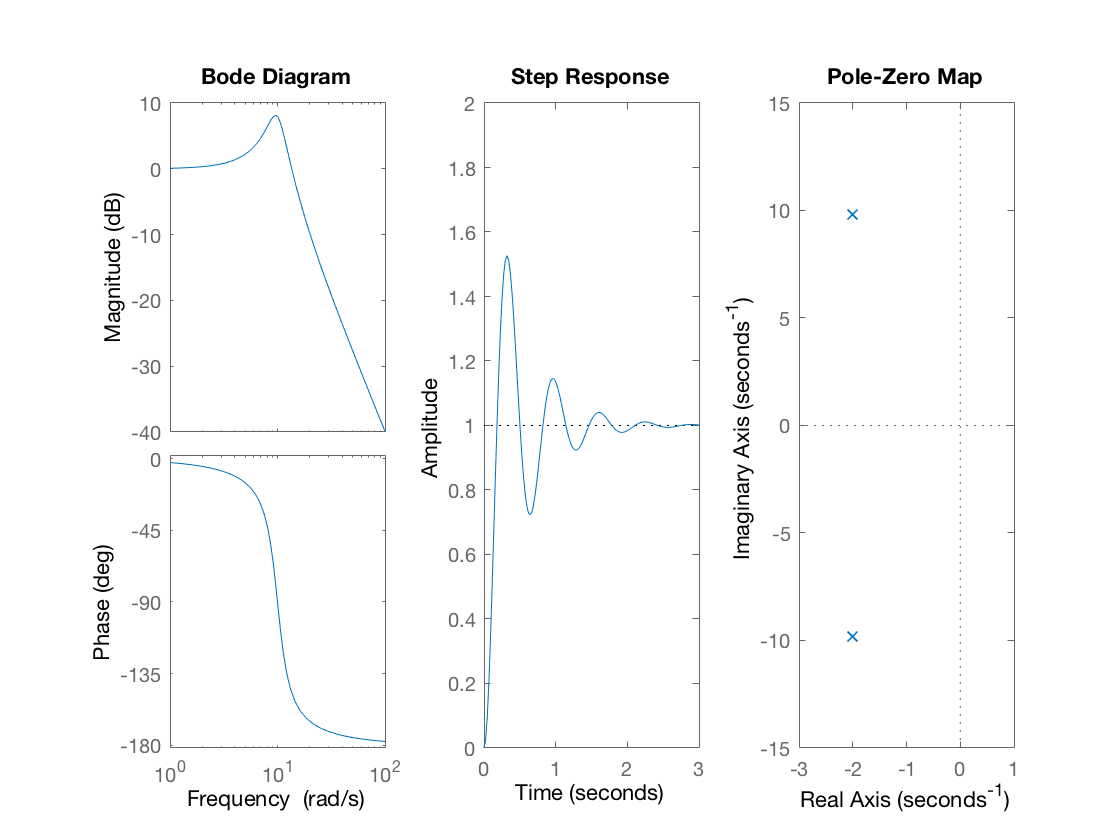


%plot -s 560,420
w_n = 10;
zeta = 0.2;

s = tf('s');
G1 = w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);


%plot -s 1200,300
subplot(1,3,3), pzmap(G1), axis([-3 1 -15 15])
subplot(1,3,2), step(G1), axis([0 3 0 2])
subplot(1,3,1), bode(G1)